## Задание диапазонов входных параметров

%% Задание диапазонов входов модели
% Угол подъема, град
theta_min = -5;   theta_max = 15;   theta_n = 5;

% Начальная скорость, м/с
v0_min     = 10;   v0_max     = 20;   v0_n     = 5;

% Открытие дроссельной заслонки, %
throttle_min = 10;   throttle_max = 20;   throttle_n = 5;

% Разбиваем диапазоны на сетку
theta  = linspace(theta_min,  theta_max,  theta_n);
v0     = linspace(v0_min,      v0_max,     v0_n);
throttle    = linspace(throttle_min,throttle_max,throttle_n);

% Создаём полный план эксперимента (все комбинации)
[Theta, V0, Thr] = ndgrid(theta, v0, throttle);
X = [Theta(:), V0(:), Thr(:)];  % входной набор данных Nx3

%% ОСНОВНЫЕ ПАРАМЕТРЫ МОДЕЛИ Vehicle_4WD
massVehicle      = 1500;        % кг
inertiaDriveShaft = 1.1;        % кг*м²
engineRPM0       = 1000;        % об/мин
ratioDiff        = 3.5;         % передаточное число дифференциала
radiusWheel      = 0.32;        % м
tireStiffness    = 200000;      % Н/м  
tireDamping      = 5000;        % Нс/м
inertiaLateral   = 0.01;        % кг*м² боковая инерция шины

## Серия экспериментов в Simulink

%% ПЛАН ЭКСПЕРИМЕНТА
clear y_results;  % Результаты: [коэф_скольжения, конечная_скорость]
N = size(X, 1);
simTime = 1;
y_results = zeros(N, 2);  % [S, v_конеч]

%% ОСНОВНОЙ ЦИКЛ
for i = 1:N
    fprintf('Эксперимент %d/%d: theta=%.3f, throttle=%.2f, v0=%.1f\n', ...
        i, N, X(i,1), X(i,3), X(i,2));
    
    % УСТАНОВКА ПАРАМЕТРОВ
    set_param('Vehicle_4WD_NiVB/Vehicle_Body', 'v', num2str(X(i,2)));     % v0
    
    % theta и throttle  
    set_param('Vehicle_4WD_NiVB/Theta', 'Value', num2str(X(i,1)));     % theta
    set_param('Vehicle_4WD_NiVB/Thr', 'Value', num2str(X(i,3)));    % throttle
    
    % Симуляция 1 секунд
    out = sim('Vehicle_4WD_NiVB', 'StopTime', num2str(simTime));
    
    % СКОРОСТЬ ИЗ WORKSPACE (выполни whos после 1 симуляции!)
    clear time
    v_series = out.simlog_Vehicle_4WD_NiVB.Vehicle_Body.v.series;
    s_series = out.simlog_Vehicle_4WD_NiVB.Left_Rear.S.series;
    t = time(v_series);
    v = values(v_series);
    s = values(s_series);
    y(i) = mean(v(t <= simTime));
    
    % Средняя за 10с и конечная
    S = mean(s);
    v_end = v(end);
    
    y_results(i,:) = [S, v_end];

    disp(sprintf(' → подъем=%.1f, акселер=%.1f, v_нач=%.1f | v_к=%.2f, S_mean=%.3f\n', ...
        X(i,1), X(i,2), X(i,3), y_results(i,2), y_results(i,1)));
    
    %fprintf('  → подъем=%.1f, акселер=%.1f, v_нач=%.1f \n', X(i,1), X(i,2), X(i,3));
    %fprintf(' v_к=%.2f, акселер=%.1f', y_results(i,2), y_results(i,1));
    %fprintf(' S=%.1f', y_results(i,1));
end

 → подъем=-5.0, акселер=10.0, v_нач=10.0 | v_к=11.36, S_mean=-0.217



Эксперимент 2/125: theta=0.000, throttle=10.00

 → подъем=0.0, акселер=10.0, v_нач=10.0 | v_к=10.80, S_mean=-0.183



Эксперимент 3/125: theta=5.000, throttle=10.00

 → подъем=5.0, акселер=10.0, v_нач=10.0 | v_к=10.23, S_mean=-0.214



Эксперимент 4/125: theta=10.000, throttle=10.00

 → подъем=10.0, акселер=10.0, v_нач=10.0 | v_к=9.68, S_mean=-0.179



Эксперимент 5/125: theta=15.000, throttle=10.00

 → подъем=15.0, акселер=10.0, v_нач=10.0 | v_к=9.14, S_mean=-0.241



Эксперимент 6/125: theta=-5.000, throttle=10.00

 → подъем=-5.0, акселер=12.5, v_нач=10.0 | v_к=13.00, S_mean=-0.244



Эксперимент 7/125: theta=0.000, throttle=10.00

 → подъем=0.0, акселер=12.5, v_нач=10.0 | v_к=12.42, S_mean=-0.219



Эксперимент 8/125: theta=5.000, throttle=10.00

 → подъем=5.0, акселер=12.5, v_нач=10.0 | v_к=11.85, S_mean=-0.241



Эксперимент 9/125: theta=10.000, throttle=10.00

 → подъем=10.0, акселер=12.5, v_нач=10.0 | v_к=11.29, S_mean=-0.240



Эксперимент 10/125: theta=15.000, throttle=10.00

 → подъем=15.0, акселер=12.5, v_нач=10.0 | v_к=10.74, S_mean=-0.199



Эксперимент 11/125: theta=-5.000, throttle=10.00

 → подъем=-5.0, акселер=15.0, v_нач=10.0 | v_к=14.65, S_mean=-0.213



Эксперимент 12/125: theta=0.000, throttle=10.00

 → подъем=0.0, акселер=15.0, v_нач=10.0 | v_к=14.07, S_mean=-0.228



Эксперимент 13/125: theta=5.000, throttle=10.00

 → подъем=5.0, акселер=15.0, v_нач=10.0 | v_к=13.50, S_mean=-0.274



Эксперимент 14/125: theta=10.000, throttle=10.00

 → подъем=10.0, акселер=15.0, v_нач=10.0 | v_к=12.93, S_mean=-0.255



Эксперимент 15/125: theta=15.000, throttle=10.00

 → подъем=15.0, акселер=15.0, v_нач=10.0 | v_к=12.38, S_mean=-0.264



Эксперимент 16/125: theta=-5.000, throttle=10.00

 → подъем=-5.0, акселер=17.5, v_нач=10.0 | v_к=16.27, S_mean=-0.242



Эксперимент 17/125: theta=0.000, throttle=10.00

 → подъем=0.0, акселер=17.5, v_нач=10.0 | v_к=15.70, S_mean=-0.298



Эксперимент 18/125: theta=5.000, throttle=10.00

 → подъем=5.0, акселер=17.5, v_нач=10.0 | v_к=15.14, S_mean=-0.227



Эксперимент 19/125: theta=10.000, throttle=10.00

 → подъем=10.0, акселер=17.5, v_нач=10.0 | v_к=14.57, S_mean=-0.231



Эксперимент 20/125: theta=15.000, throttle=10.00

 → подъем=15.0, акселер=17.5, v_нач=10.0 | v_к=14.02, S_mean=-0.263



Эксперимент 21/125: theta=-5.000, throttle=10.00

 → подъем=-5.0, акселер=20.0, v_нач=10.0 | v_к=17.87, S_mean=-0.263



Эксперимент 22/125: theta=0.000, throttle=10.00

 → подъем=0.0, акселер=20.0, v_нач=10.0 | v_к=17.31, S_mean=-0.324



Эксперимент 23/125: theta=5.000, throttle=10.00

 → подъем=5.0, акселер=20.0, v_нач=10.0 | v_к=16.75, S_mean=-0.293



Эксперимент 24/125: theta=10.000, throttle=10.00

 → подъем=10.0, акселер=20.0, v_нач=10.0 | v_к=16.19, S_mean=-0.243



Эксперимент 25/125: theta=15.000, throttle=10.00

 → подъем=15.0, акселер=20.0, v_нач=10.0 | v_к=15.64, S_mean=-0.291



Эксперимент 26/125: theta=-5.000, throttle=12.50

 → подъем=-5.0, акселер=10.0, v_нач=12.5 | v_к=11.36, S_mean=-0.217



Эксперимент 27/125: theta=0.000, throttle=12.50

 → подъем=0.0, акселер=10.0, v_нач=12.5 | v_к=10.80, S_mean=-0.183



Эксперимент 28/125: theta=5.000, throttle=12.50

 → подъем=5.0, акселер=10.0, v_нач=12.5 | v_к=10.23, S_mean=-0.214



Эксперимент 29/125: theta=10.000, throttle=12.50

 → подъем=10.0, акселер=10.0, v_нач=12.5 | v_к=9.68, S_mean=-0.179



Эксперимент 30/125: theta=15.000, throttle=12.50

 → подъем=15.0, акселер=10.0, v_нач=12.5 | v_к=9.14, S_mean=-0.241



Эксперимент 31/125: theta=-5.000, throttle=12.50

 → подъем=-5.0, акселер=12.5, v_нач=12.5 | v_к=13.00, S_mean=-0.244



Эксперимент 32/125: theta=0.000, throttle=12.50

 → подъем=0.0, акселер=12.5, v_нач=12.5 | v_к=12.42, S_mean=-0.219



Эксперимент 33/125: theta=5.000, throttle=12.50

 → подъем=5.0, акселер=12.5, v_нач=12.5 | v_к=11.85, S_mean=-0.241



Эксперимент 34/125: theta=10.000, throttle=12.50

 → подъем=10.0, акселер=12.5, v_нач=12.5 | v_к=11.29, S_mean=-0.240



Эксперимент 35/125: theta=15.000, throttle=12.50

 → подъем=15.0, акселер=12.5, v_нач=12.5 | v_к=10.74, S_mean=-0.199



Эксперимент 36/125: theta=-5.000, throttle=12.50

 → подъем=-5.0, акселер=15.0, v_нач=12.5 | v_к=14.65, S_mean=-0.213



Эксперимент 37/125: theta=0.000, throttle=12.50

 → подъем=0.0, акселер=15.0, v_нач=12.5 | v_к=14.07, S_mean=-0.228



Эксперимент 38/125: theta=5.000, throttle=12.50

 → подъем=5.0, акселер=15.0, v_нач=12.5 | v_к=13.50, S_mean=-0.274



Эксперимент 39/125: theta=10.000, throttle=12.50

 → подъем=10.0, акселер=15.0, v_нач=12.5 | v_к=12.93, S_mean=-0.255



Эксперимент 40/125: theta=15.000, throttle=12.50

 → подъем=15.0, акселер=15.0, v_нач=12.5 | v_к=12.38, S_mean=-0.264



Эксперимент 41/125: theta=-5.000, throttle=12.50

 → подъем=-5.0, акселер=17.5, v_нач=12.5 | v_к=16.27, S_mean=-0.242



Эксперимент 42/125: theta=0.000, throttle=12.50

 → подъем=0.0, акселер=17.5, v_нач=12.5 | v_к=15.70, S_mean=-0.298



Эксперимент 43/125: theta=5.000, throttle=12.50

 → подъем=5.0, акселер=17.5, v_нач=12.5 | v_к=15.14, S_mean=-0.227



Эксперимент 44/125: theta=10.000, throttle=12.50

 → подъем=10.0, акселер=17.5, v_нач=12.5 | v_к=14.57, S_mean=-0.231



Эксперимент 45/125: theta=15.000, throttle=12.50

 → подъем=15.0, акселер=17.5, v_нач=12.5 | v_к=14.02, S_mean=-0.263



Эксперимент 46/125: theta=-5.000, throttle=12.50

 → подъем=-5.0, акселер=20.0, v_нач=12.5 | v_к=17.87, S_mean=-0.263



Эксперимент 47/125: theta=0.000, throttle=12.50

 → подъем=0.0, акселер=20.0, v_нач=12.5 | v_к=17.31, S_mean=-0.324



Эксперимент 48/125: theta=5.000, throttle=12.50

 → подъем=5.0, акселер=20.0, v_нач=12.5 | v_к=16.75, S_mean=-0.293



Эксперимент 49/125: theta=10.000, throttle=12.50

 → подъем=10.0, акселер=20.0, v_нач=12.5 | v_к=16.19, S_mean=-0.243



Эксперимент 50/125: theta=15.000, throttle=12.50

 → подъем=15.0, акселер=20.0, v_нач=12.5 | v_к=15.64, S_mean=-0.291



Эксперимент 51/125: theta=-5.000, throttle=15.00

 → подъем=-5.0, акселер=10.0, v_нач=15.0 | v_к=11.36, S_mean=-0.217



Эксперимент 52/125: theta=0.000, throttle=15.00

 → подъем=0.0, акселер=10.0, v_нач=15.0 | v_к=10.80, S_mean=-0.183



Эксперимент 53/125: theta=5.000, throttle=15.00

 → подъем=5.0, акселер=10.0, v_нач=15.0 | v_к=10.23, S_mean=-0.214



Эксперимент 54/125: theta=10.000, throttle=15.00

 → подъем=10.0, акселер=10.0, v_нач=15.0 | v_к=9.68, S_mean=-0.179



Эксперимент 55/125: theta=15.000, throttle=15.00

 → подъем=15.0, акселер=10.0, v_нач=15.0 | v_к=9.14, S_mean=-0.241



Эксперимент 56/125: theta=-5.000, throttle=15.00

 → подъем=-5.0, акселер=12.5, v_нач=15.0 | v_к=13.00, S_mean=-0.244



Эксперимент 57/125: theta=0.000, throttle=15.00

 → подъем=0.0, акселер=12.5, v_нач=15.0 | v_к=12.42, S_mean=-0.219



Эксперимент 58/125: theta=5.000, throttle=15.00

 → подъем=5.0, акселер=12.5, v_нач=15.0 | v_к=11.85, S_mean=-0.241



Эксперимент 59/125: theta=10.000, throttle=15.00

 → подъем=10.0, акселер=12.5, v_нач=15.0 | v_к=11.29, S_mean=-0.240



Эксперимент 60/125: theta=15.000, throttle=15.00

 → подъем=15.0, акселер=12.5, v_нач=15.0 | v_к=10.74, S_mean=-0.199



Эксперимент 61/125: theta=-5.000, throttle=15.00

 → подъем=-5.0, акселер=15.0, v_нач=15.0 | v_к=14.65, S_mean=-0.213



Эксперимент 62/125: theta=0.000, throttle=15.00

 → подъем=0.0, акселер=15.0, v_нач=15.0 | v_к=14.07, S_mean=-0.228



Эксперимент 63/125: theta=5.000, throttle=15.00

 → подъем=5.0, акселер=15.0, v_нач=15.0 | v_к=13.50, S_mean=-0.274



Эксперимент 64/125: theta=10.000, throttle=15.00

 → подъем=10.0, акселер=15.0, v_нач=15.0 | v_к=12.93, S_mean=-0.255



Эксперимент 65/125: theta=15.000, throttle=15.00

 → подъем=15.0, акселер=15.0, v_нач=15.0 | v_к=12.38, S_mean=-0.264



Эксперимент 66/125: theta=-5.000, throttle=15.00

 → подъем=-5.0, акселер=17.5, v_нач=15.0 | v_к=16.27, S_mean=-0.242



Эксперимент 67/125: theta=0.000, throttle=15.00

 → подъем=0.0, акселер=17.5, v_нач=15.0 | v_к=15.70, S_mean=-0.298



Эксперимент 68/125: theta=5.000, throttle=15.00

 → подъем=5.0, акселер=17.5, v_нач=15.0 | v_к=15.14, S_mean=-0.227



Эксперимент 69/125: theta=10.000, throttle=15.00

 → подъем=10.0, акселер=17.5, v_нач=15.0 | v_к=14.57, S_mean=-0.231



Эксперимент 70/125: theta=15.000, throttle=15.00

 → подъем=15.0, акселер=17.5, v_нач=15.0 | v_к=14.02, S_mean=-0.263



Эксперимент 71/125: theta=-5.000, throttle=15.00

 → подъем=-5.0, акселер=20.0, v_нач=15.0 | v_к=17.87, S_mean=-0.263



Эксперимент 72/125: theta=0.000, throttle=15.00

 → подъем=0.0, акселер=20.0, v_нач=15.0 | v_к=17.31, S_mean=-0.324



Эксперимент 73/125: theta=5.000, throttle=15.00

 → подъем=5.0, акселер=20.0, v_нач=15.0 | v_к=16.75, S_mean=-0.293



Эксперимент 74/125: theta=10.000, throttle=15.00

 → подъем=10.0, акселер=20.0, v_нач=15.0 | v_к=16.19, S_mean=-0.243



Эксперимент 75/125: theta=15.000, throttle=15.00

 → подъем=15.0, акселер=20.0, v_нач=15.0 | v_к=15.64, S_mean=-0.291



Эксперимент 76/125: theta=-5.000, throttle=17.50

 → подъем=-5.0, акселер=10.0, v_нач=17.5 | v_к=11.36, S_mean=-0.217



Эксперимент 77/125: theta=0.000, throttle=17.50

 → подъем=0.0, акселер=10.0, v_нач=17.5 | v_к=10.80, S_mean=-0.183



Эксперимент 78/125: theta=5.000, throttle=17.50

 → подъем=5.0, акселер=10.0, v_нач=17.5 | v_к=10.23, S_mean=-0.214



Эксперимент 79/125: theta=10.000, throttle=17.50

 → подъем=10.0, акселер=10.0, v_нач=17.5 | v_к=9.68, S_mean=-0.179



Эксперимент 80/125: theta=15.000, throttle=17.50

 → подъем=15.0, акселер=10.0, v_нач=17.5 | v_к=9.14, S_mean=-0.241



Эксперимент 81/125: theta=-5.000, throttle=17.50

 → подъем=-5.0, акселер=12.5, v_нач=17.5 | v_к=13.00, S_mean=-0.244



Эксперимент 82/125: theta=0.000, throttle=17.50

 → подъем=0.0, акселер=12.5, v_нач=17.5 | v_к=12.42, S_mean=-0.219



Эксперимент 83/125: theta=5.000, throttle=17.50

 → подъем=5.0, акселер=12.5, v_нач=17.5 | v_к=11.85, S_mean=-0.241



Эксперимент 84/125: theta=10.000, throttle=17.50

 → подъем=10.0, акселер=12.5, v_нач=17.5 | v_к=11.29, S_mean=-0.240



Эксперимент 85/125: theta=15.000, throttle=17.50

 → подъем=15.0, акселер=12.5, v_нач=17.5 | v_к=10.74, S_mean=-0.199



Эксперимент 86/125: theta=-5.000, throttle=17.50

 → подъем=-5.0, акселер=15.0, v_нач=17.5 | v_к=14.65, S_mean=-0.213



Эксперимент 87/125: theta=0.000, throttle=17.50

 → подъем=0.0, акселер=15.0, v_нач=17.5 | v_к=14.07, S_mean=-0.228



Эксперимент 88/125: theta=5.000, throttle=17.50

 → подъем=5.0, акселер=15.0, v_нач=17.5 | v_к=13.50, S_mean=-0.274



Эксперимент 89/125: theta=10.000, throttle=17.50

 → подъем=10.0, акселер=15.0, v_нач=17.5 | v_к=12.93, S_mean=-0.255



Эксперимент 90/125: theta=15.000, throttle=17.50

 → подъем=15.0, акселер=15.0, v_нач=17.5 | v_к=12.38, S_mean=-0.264



Эксперимент 91/125: theta=-5.000, throttle=17.50

 → подъем=-5.0, акселер=17.5, v_нач=17.5 | v_к=16.27, S_mean=-0.242



Эксперимент 92/125: theta=0.000, throttle=17.50

 → подъем=0.0, акселер=17.5, v_нач=17.5 | v_к=15.70, S_mean=-0.298



Эксперимент 93/125: theta=5.000, throttle=17.50

 → подъем=5.0, акселер=17.5, v_нач=17.5 | v_к=15.14, S_mean=-0.227



Эксперимент 94/125: theta=10.000, throttle=17.50

 → подъем=10.0, акселер=17.5, v_нач=17.5 | v_к=14.57, S_mean=-0.231



Эксперимент 95/125: theta=15.000, throttle=17.50

 → подъем=15.0, акселер=17.5, v_нач=17.5 | v_к=14.02, S_mean=-0.263



Эксперимент 96/125: theta=-5.000, throttle=17.50

 → подъем=-5.0, акселер=20.0, v_нач=17.5 | v_к=17.87, S_mean=-0.263



Эксперимент 97/125: theta=0.000, throttle=17.50

 → подъем=0.0, акселер=20.0, v_нач=17.5 | v_к=17.31, S_mean=-0.324



Эксперимент 98/125: theta=5.000, throttle=17.50

 → подъем=5.0, акселер=20.0, v_нач=17.5 | v_к=16.75, S_mean=-0.293



Эксперимент 99/125: theta=10.000, throttle=17.50

 → подъем=10.0, акселер=20.0, v_нач=17.5 | v_к=16.19, S_mean=-0.243



Эксперимент 100/125: theta=15.000, throttle=17.50

 → подъем=15.0, акселер=20.0, v_нач=17.5 | v_к=15.64, S_mean=-0.291



Эксперимент 101/125: theta=-5.000, throttle=20.00

 → подъем=-5.0, акселер=10.0, v_нач=20.0 | v_к=11.36, S_mean=-0.217



Эксперимент 102/125: theta=0.000, throttle=20.00

 → подъем=0.0, акселер=10.0, v_нач=20.0 | v_к=10.80, S_mean=-0.183



Эксперимент 103/125: theta=5.000, throttle=20.00

 → подъем=5.0, акселер=10.0, v_нач=20.0 | v_к=10.23, S_mean=-0.214



Эксперимент 104/125: theta=10.000, throttle=20.00

 → подъем=10.0, акселер=10.0, v_нач=20.0 | v_к=9.68, S_mean=-0.179



Эксперимент 105/125: theta=15.000, throttle=20.00

 → подъем=15.0, акселер=10.0, v_нач=20.0 | v_к=9.14, S_mean=-0.241



Эксперимент 106/125: theta=-5.000, throttle=20.00

 → подъем=-5.0, акселер=12.5, v_нач=20.0 | v_к=13.00, S_mean=-0.244



Эксперимент 107/125: theta=0.000, throttle=20.00

 → подъем=0.0, акселер=12.5, v_нач=20.0 | v_к=12.42, S_mean=-0.219



Эксперимент 108/125: theta=5.000, throttle=20.00

 → подъем=5.0, акселер=12.5, v_нач=20.0 | v_к=11.85, S_mean=-0.241



Эксперимент 109/125: theta=10.000, throttle=20.00

 → подъем=10.0, акселер=12.5, v_нач=20.0 | v_к=11.29, S_mean=-0.240



Эксперимент 110/125: theta=15.000, throttle=20.00

 → подъем=15.0, акселер=12.5, v_нач=20.0 | v_к=10.74, S_mean=-0.199



Эксперимент 111/125: theta=-5.000, throttle=20.00

 → подъем=-5.0, акселер=15.0, v_нач=20.0 | v_к=14.65, S_mean=-0.213



Эксперимент 112/125: theta=0.000, throttle=20.00

 → подъем=0.0, акселер=15.0, v_нач=20.0 | v_к=14.07, S_mean=-0.228



Эксперимент 113/125: theta=5.000, throttle=20.00

 → подъем=5.0, акселер=15.0, v_нач=20.0 | v_к=13.50, S_mean=-0.274



Эксперимент 114/125: theta=10.000, throttle=20.00

 → подъем=10.0, акселер=15.0, v_нач=20.0 | v_к=12.93, S_mean=-0.255



Эксперимент 115/125: theta=15.000, throttle=20.00

 → подъем=15.0, акселер=15.0, v_нач=20.0 | v_к=12.38, S_mean=-0.264



Эксперимент 116/125: theta=-5.000, throttle=20.00

 → подъем=-5.0, акселер=17.5, v_нач=20.0 | v_к=16.27, S_mean=-0.242



Эксперимент 117/125: theta=0.000, throttle=20.00

 → подъем=0.0, акселер=17.5, v_нач=20.0 | v_к=15.70, S_mean=-0.298



Эксперимент 118/125: theta=5.000, throttle=20.00

 → подъем=5.0, акселер=17.5, v_нач=20.0 | v_к=15.14, S_mean=-0.227



Эксперимент 119/125: theta=10.000, throttle=20.00

 → подъем=10.0, акселер=17.5, v_нач=20.0 | v_к=14.57, S_mean=-0.231



Эксперимент 120/125: theta=15.000, throttle=20.00

 → подъем=15.0, акселер=17.5, v_нач=20.0 | v_к=14.02, S_mean=-0.263



Эксперимент 121/125: theta=-5.000, throttle=20.00

 → подъем=-5.0, акселер=20.0, v_нач=20.0 | v_к=17.87, S_mean=-0.263



Эксперимент 122/125: theta=0.000, throttle=20.00

 → подъем=0.0, акселер=20.0, v_нач=20.0 | v_к=17.31, S_mean=-0.324



Эксперимент 123/125: theta=5.000, throttle=20.00

 → подъем=5.0, акселер=20.0, v_нач=20.0 | v_к=16.75, S_mean=-0.293



Эксперимент 124/125: theta=10.000, throttle=20.00

 → подъем=10.0, акселер=20.0, v_нач=20.0 | v_к=16.19, S_mean=-0.243



Эксперимент 125/125: theta=15.000, throttle=20.00

 → подъем=15.0, акселер=20.0, v_нач=20.0 | v_к=15.64, S_mean=-0.291




%% РЕЗУЛЬТАТЫ
fprintf('\n %d экспериментов\n', N);


 125 экспериментов


disp('X = [theta, throttle, v0]');

X = [theta, throttle, v0]


disp('y_results = [v_ср_10с, v_конец]');

y_results = [v_ср_10с, v_конец]


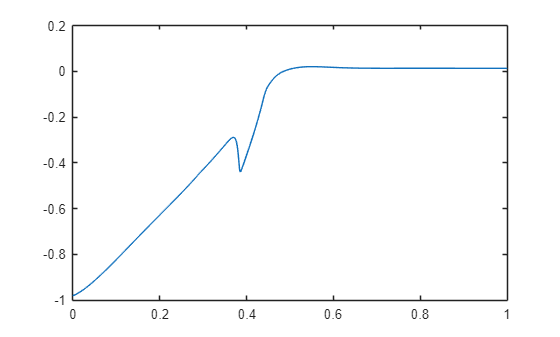

% 3. График 
plot(time(out.simlog_Vehicle_4WD_NiVB.Vehicle_Body.v.series), ...
     values(out.simlog_Vehicle_4WD_NiVB.Left_Rear.S.series));

##  Подготовка данных и нормировка

clear functions

%% Безопасная очистка NaN
valid_x = all(~isnan(X), 2);           % N×1 для X
valid_y = ~isnan(y(:));               % N×1 для y
valid = valid_x & valid_y;             % N×1 логический!

fprintf('valid: %dx%d (%d true)\n', size(valid), sum(valid));

valid: 125x1 (125 true)



% ИНДЕКСИРУЕМ
X_clean = X(valid, :);
y_clean = y(valid);

% Нормировка
X_norm = (X_clean - min(X_clean)) ./ (max(X_clean) - min(X_clean));
y_norm = (y_clean - min(y_clean)) ./ (max(y_clean) - min(y_clean));

fprintf('Готово! X_norm: %dx%d\n', size(X_norm));

Готово! X_norm: 125x3


## Интерфейс с ползунками (Live Editor)

Создайте в Live Editor интерактивные элементы:

- 3 ползунка для числа нейронов в слоях 2–4 (5‑слойная сеть),

- 1 ползунок для числа эпох.

%% Интерактивные параметры (Live Editor)
% Ползунки должны быть вставлены через Live Editor → Insert → Slider
% или интерактивный код (опционально, зависит от версии).

% Пример переменных, которые можно связать с ползунками:
%   HiddenUnit1, HiddenUnit2, HiddenUnit3, HiddenUnit4, HiddenUnit5
%   NumEpochs

HiddenUnit1 = 128;   % например
HiddenUnit2 = 64;
HiddenUnit3 = 32;
HiddenUnit4 = 32;
HiddenUnit5 = 16;
NumEpochs   = 200;

## Создание и обучение нейросети

%% ✅ РАБОЧАЯ нейросеть VehКорicle_4WD (125x3 → 125x2)
numObs = size(X_norm, 1);  % 125 образцов
inputSize = size(X_norm, 2);  % 3 входа

% ✅ ДАННЫЕ в формате MATLAB (N x features)
fprintf('X_norm: %dx%d\n', size(X_norm));     % 125x3

X_norm: 125x3


fprintf('y_results: %dx%d\n', size(y_results)); % 125x2

y_results: 125x2


Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:06 |        13.65 |         93.2 |          0.0010 |
|       8 |          50 |       00:00:07 |         8.45 |         35.7 |          0.0010 |
|      15 |         100 |       00:00:08 |         2.58 |          3.3 |          0.0010 |
|      22 |         150 |       00:00:09 |         2.29 |          2.6 |          0.0010 |
|      29 |         200 |       00:00:10 |         1.38 |          1.0 |          0.0010 |
|      36 |         250 |       00:00:11 |         0.64 |          0.2 |          0.0010 |
|      43 |         300 |       00:00:12 |         0.43 |      9.3

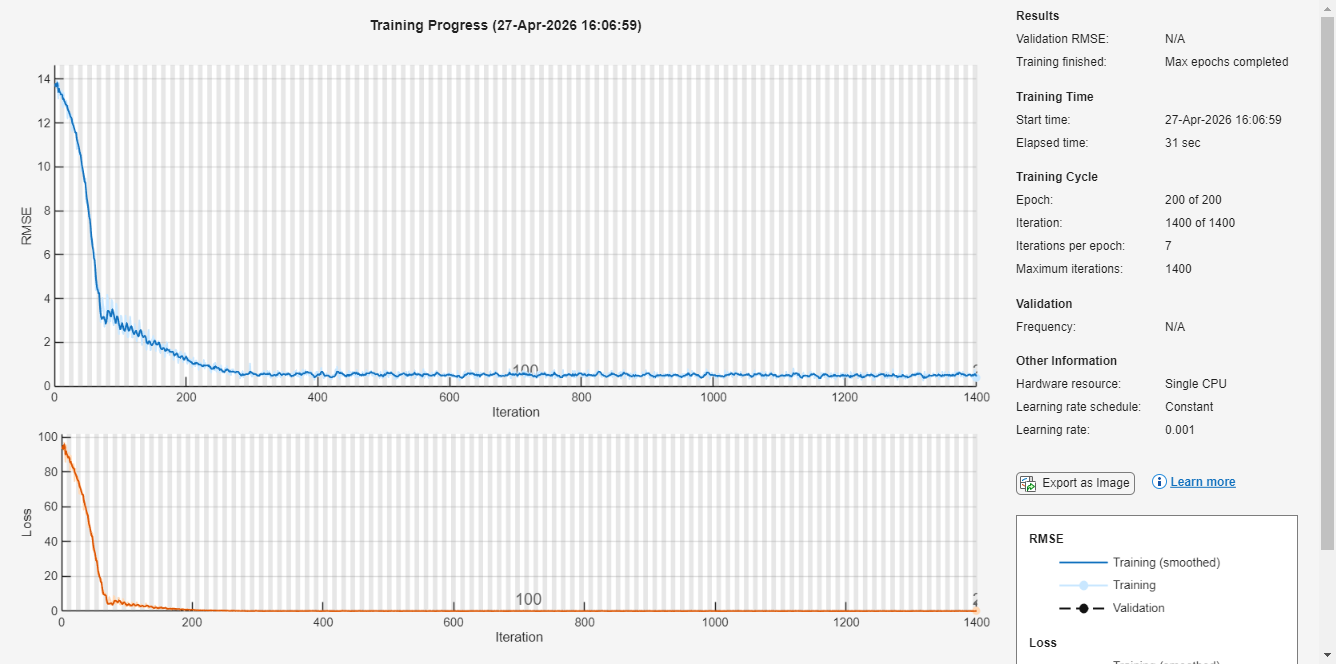


layers = [
    featureInputLayer(inputSize)
    fullyConnectedLayer(128)
    reluLayer
    dropoutLayer(0.1)
    fullyConnectedLayer(64)
    reluLayer
    fullyConnectedLayer(2)  % 2 выхода
    regressionLayer
];

options = trainingOptions('adam', ...
    'MaxEpochs', 200, ...
    'MiniBatchSize', 16, ...
    'Plots', 'training-progress');

% ✅ trainNetwork(X, Y, layers, options) - N x features!
net = trainNetwork(X_norm, y_results, layers, options);

##  Графики результатов

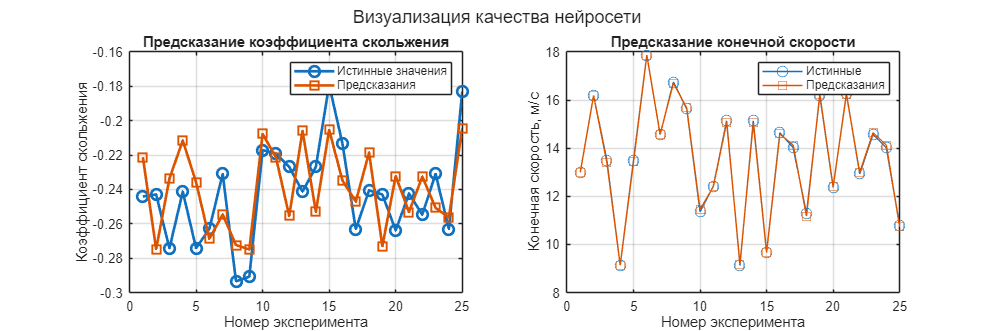

%% ✅ ВИЗУАЛИЗАЦИЯ результатов нейросети
% Разделим данные на train/test (20% тест)
N = size(X_norm,1);
test_idx = randsample(N, round(0.2*N), false);  % 20% случайных
train_idx = ~ismember(1:N, test_idx);


X_test = X_norm(test_idx, :);
ytest = y_results(test_idx, 1);  % ← Истинные S
y_test_pred = predict(net, X_test);  % Предсказания

%% ГРАФИКИ
figure('Position', [100 100 1200 400]);

% График 1: S (Коэффициент скольжения)
subplot(1,2,1);
plot(ytest, 'o-', 'DisplayName', 'Истинные значения', 'MarkerSize', 8, 'LineWidth', 2);
hold on;
plot(y_test_pred(:,1), 's-', 'DisplayName', 'Предсказания', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Номер эксперимента'); ylabel('Коэффициент скольжения');
title('Предсказание коэффициента скольжения'); legend; grid on;

% График 2: v_конец (конечная скорость)  
subplot(1,2,2);
plot(y_results(test_idx,2), 'o-', 'DisplayName', 'Истинные', 'MarkerSize', 8);
hold on;
plot(y_test_pred(:,2), 's-', 'DisplayName', 'Предсказания', 'MarkerSize', 8);
xlabel('Номер эксперимента'); ylabel('Конечная скорость, м/с');
title('Предсказание конечной скорости'); legend; grid on;

sgtitle('Визуализация качества нейросети');

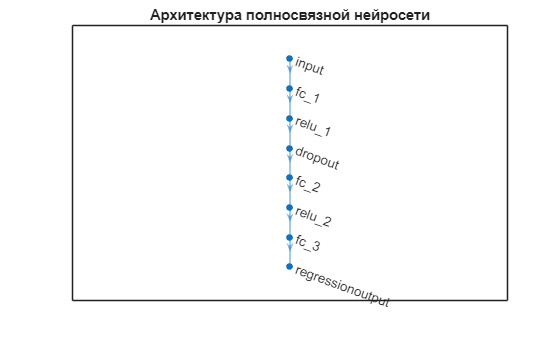


% Архитектура сети
figure
plot(net)
title('Архитектура полносвязной нейросети')

## Оценка качества

% Метрики
rmse_S = sqrt(mean((ytest - y_test_pred(:,1)).^2));
rmse_end = sqrt(mean((y_results(test_idx,2) - y_test_pred(:,2)).^2));

fprintf('RMSE S: %.3f \n', rmse_S);

RMSE S: 0.024 


fprintf('RMSE v_конеч: %.3f м/с\n', rmse_end);

RMSE v_конеч: 0.061 м/с


fprintf('R² = %.3f\n', 1 - mean((ytest - y_test_pred(:,1)).^2)/var(ytest));

R² = 0.250



analyzeNetwork(net)

Время симуляции

% Время симуляции имитационной моделью
tic; % включение счетчика
sim('Vehicle_4WD_NiVB', 'StopTime', num2str(simTime));
T_sim = toc; % выключение счетчика, запись времени симуляции

%Время нейросети
tic;
y_pred_norm = predict(net, X_norm(end,:)); %на примере последней точки плана 
T_pred = toc;

fprintf(' Имитационная модель:\n  Время: %g мс\n', T_sim * 1000);

 Имитационная модель:
  Время: 5308.15 мс


fprintf('   Суррогатная нейросеть:\n  Время: %g мс\n', T_pred * 1000);

   Суррогатная нейросеть:
  Время: 203.553 мс


fprintf('  Отношение (Sim → ANN): %.1fx\n', T_sim / T_pred);

  Отношение (Sim → ANN): 26.1x
